# Osprey Walkthrough

*Georg Oeltzschner, 2021.*

Welcome to this MATLAB live script! This workbook has been written to give you a little more detailed insight into the nuts and bolts data analysis pipeline of Osprey. This will hopefully empower and encourage you to make local modifications that are particularly suited for your type of data, and maybe even contribute to the continuous development of the Osprey platform by submitting your improvements back to the repository!

Osprey is an all-in-one open-source software suite for state-of-the art processing and quantitative analysis of in-vivo MRS data. It is available free of charge from the [Osprey GitHub repository](https://github.com/schorschinho/osprey).

You can find the comprehensive [Osprey documentation here](https://schorschinho.github.io/osprey).

## Getting set up

To enable you to use the GUI and produce output plots, please download and install the following toolboxes from the MATLAB File Exchange:

- [GUI Layout Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/47982-gui-layout-toolbox) (David Sampson)

- [Widget Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/66235-widgets-toolbox) (Robin Jackey)

Both toolboxes are also included in this workshop-specific repository. You can double-click to install. MATLAB will automatically add the toolboxes to its path.

To perform voxel co-registration and tissue segmentation, download **SPM12 **[from the UCL website](http://www.fil.ion.ucl.ac.uk/spm/software/spm12/), then extract and add to your MATLAB path (at the same level as the Osprey folder, ideally). SPM12 is also added in this workshop-specific repository.

For further detail on getting Osprey completely set up on your computer, please follow the steps outlined in the [Osprey documentation](https://schorschinho.github.io/osprey/getting-started.html#installing-osprey).

### System requirements

We have tested this live script using MATLAB version 2019b on MacOS Big Sur 11.5.2.

Osprey includes compiled LCModel binaries for macOS and Windows 10 (64-bit). These *should* work out of the box if you have a compatible system. While we intend to collect pre-compiled binaries for other systems in our [LCModel GitHub repository](https://github.com/schorschinho/lcmodel), you can learn how to compile LCModel on your own system [here](https://forum.mrshub.org/t/building-lcmodel/317).

## The Osprey workflow in a nutshell

Osprey was designed to have an easy, linear workflow with as little user input as possible. It has many built-in routines to recognize data formats and sequence types, and will be able to perform most required processing steps automatically. Osprey consists of seven separate modules – Job, Load, Proc, Fit, Coreg, Seg, and Quant, all of which are sequentially called. This can either be done from the MATLAB command prompt, or in a graphical user interface.

Some input will need to be provided by the user in the form of a *job*. A job specifies the locations of the files containing MRS and structural imaging data, the type of MRS sequence, and some basic control options over the data modeling procedure. While a job is progressing through the Osprey pipeline, all raw and processed data associated with this job are stored in a MATLAB structure, the Osprey *data container*. By default, this container is called `MRSCont`, but you are free to give it a more meaningful variable name.

Osprey’s data handling is based in large parts on the [free MATLAB toolbox FID-A](https://github.com/CIC-methods/FID-A). The Osprey folder contains a library of, sometimes modified, FID-A functions and additions. Please make sure that you do **not** include an installation of the original FID-A suite in your MATLAB path, as some functions in the Osprey folder might be shadowed by FID-A functions with the same name.

The `MRSCont` data container functions as a super-structure, containing FID-A structures for each dataset and processing step, along with additional information, e.g. quality metrics, quantification results, etc.

## Creating a job file

Every Osprey analysis requires the user to provide a job file. The Osprey job file is the only direct point of contact between the user and the  analysis. It contains paths to MRS data files and structural images,  defines processing and modelling options, and determines whether (and where) output files are being saved.

The job file system ensures that all processing, modeling, and quantification steps are performed in an operator-independent, reproducible way.

For this demo, we will use example files in the Siemens `.dat` format (exported through the TWIX console). 

## Running the analysis - Demonstration data

Running an analysis with Osprey is a straightforward succession of commands, since it is designed to minimize user interaction. Let's familiarize ourselves with the basic Osprey commands and workflow, and look what they do to the data.

% Clear the workspace
clear;

% Remove Osprey-DWMRS branch path
pathOspreyDW = fullfile(pwd, 'osprey-dwmrs');
rmpath(genpath(pathOspreyDW));

% Add Osprey path
pathOsprey = fullfile(pwd, 'osprey-develop');
addpath(genpath(pathOsprey));

### Initialize the job

Let us now create variables pointing to the path of the job file, and then initialize our Osprey data container. The function taking care of parsing the job file, looking for errors and inconsistencies is called `OspreyJob`. We'll pass the job file name as the argument, along with two additional arguments that will prevent Osprey from asking stupid questions (like the one whether you really want to overwrite the existing output data... this is a safety mechanism that we can safely ignore for the purpose of this workbook).

% Point to the job file
jobFileDemo = fullfile(pathOsprey, 'exampledata', 'twix', 'jobTwix.m');

% Let's look at the job file
edit(jobFileDemo);

% Start loading the job files
[demo] = OspreyJob(jobFileDemo, 0, '11');

Continue with loading new job, overwriting existing job.
/Users/Georg/Desktop/osprey-dw-workshop/osprey-develop/exampledata/twix/jobTwix.m
Timestamp September 23, 2021 13:25:55 Osprey 1.1.0


Let's look at what we created here:

demo

demo = struct with fields:
           flags: [1×1 struct]
            opts: [1×1 struct]
       ospFolder: '/Users/Georg/Desktop/osprey-dw-workshop/osprey-develop'
           files: {1×2 cell}
        files_mm: {}
       files_ref: {1×2 cell}
         files_w: {}
       file_stat: '/Users/Georg/Desktop/osprey-dw-workshop/osprey-develop/exampledata/twix/stat.csv'
       files_nii: {1×2 cell}
     files_sense: {}
    outputFolder: '/Users/Georg/Desktop/osprey-dw-workshop/osprey-develop/exampledata/twix/derivatives'
        colormap: [1×1 struct]
       loadedJob: '/Users/Georg/Desktop/osprey-dw-workshop/osprey-develop/exampledata/twix/jobTwix.m'
             ver: [1×1 struct]
      outputFile: 'jobTwix.mat'


`demo` is the name we chose for the Osprey data container. Nothing much has happened, except that it has been initialized with a bunch of settings, flags and options, and pointers to the files we want to load from and save our data to. If you like, you can examine the `flags` and `opts` structs further, but let's not bother with this for too long.

## Load raw data

The second main Osprey command is `OspreyLoad`, which contains a whole host of loader functions for the different file formats, including the Siemens raw data format (`.dat`) that the data are provided in. We'll now run `OspreyLoad`, simply by executing it on the `demo` container itself.

% Load the raw data
[demo] = OspreyLoad(demo);

Timestamp September 23, 2021 13:25:55 Osprey 1.1.0  OspreyLoad
Loading raw data from dataset   1 out of   2 total datasets...
Software version: VD (!?)
Reader version: 1496740353 (UTC: 06-Jun-2017 09:12:33)
Scan 1/2, read all mdhs:


    33.1 MB read in    2 s
Scan 2/2, read all mdhs:


    33.8 MB read in    2 s


ans = 0

multi RAID file detected.
Changed software version to VE.
Software version: VD (!?)
Reader version: 1496740353 (UTC: 06-Jun-2017 09:12:33)
Scan 1/2, read all mdhs:
    33.1 MB read in    1 s
Scan 2/2, read all mdhs:


     5.3 MB read in    0 s


ans = 0

Loading raw data from dataset   2 out of   2 total datasets...
Software version: VD (!?)
Reader version: 1496740353 (UTC: 06-Jun-2017 09:12:33)
Scan 1/2, read all mdhs:
    33.1 MB read in    2 s
Scan 2/2, read all mdhs:


    33.8 MB read in    2 s


ans = 0

multi RAID file detected.
Changed software version to VE.
Software version: VD (!?)
Reader version: 1496740353 (UTC: 06-Jun-2017 09:12:33)
Scan 1/2, read all mdhs:
    33.1 MB read in    2 s
Scan 2/2, read all mdhs:


     5.3 MB read in    0 s


ans = 0

multi RAID file detected.
Changed software version to VE.

... done.
 Elapsed time 35.598545 seconds


Osprey did what it was told to do and pulled in the data from the files specified in the job file. Raw data are stored in a FID-A data structure in the field `raw`, a cell that's capable of holding an arbitrary number of datasets with running indices (for easy batch analysis of large datasets; in this example, the batch holds two files). We can look at what we loaded there:

demo.raw{1}

ans = struct with fields:
                 fids: [2080×64 double]
                specs: [2080×64 double]
                   sz: [2080 64]
                  ppm: [1×2080 double]
                    t: [1×2080 double]
        spectralwidth: 2000
            dwelltime: 5.0000e-04
                txfrq: 123261581
                 date: ''
                 dims: [1×1 struct]
                   Bo: 2.8936
             averages: 64
          rawAverages: 64
             subspecs: 1
          rawSubspecs: 1
                  seq: 'PRESS'
                   te: 30
                   tr: 2000
    pointsToLeftshift: 0
           centerFreq: 4.7000
             geometry: [1×1 struct]
              nucleus: '1H'
             software: 've syngo MR E11'
                flags: [1×1 struct]


### Visualizing loaded data

We find a whole host of useful information that Osprey extracted from the Siemens file header, as well as the time-domain signals (1024 pts x 32 averages x 9 diffusion-weightings). We can use the function `osp_plotLoad` to visualize this. Move the slider around to change between the 2 different files. You can pass additional arguments to the function to change the visualization range and other details. Here, for example, we pass the index of the first (and only dataset) `1`, and the string `'mets'` to tell Osprey to visualize the metabolite data - but we could easily change that to water reference data, if we had any.

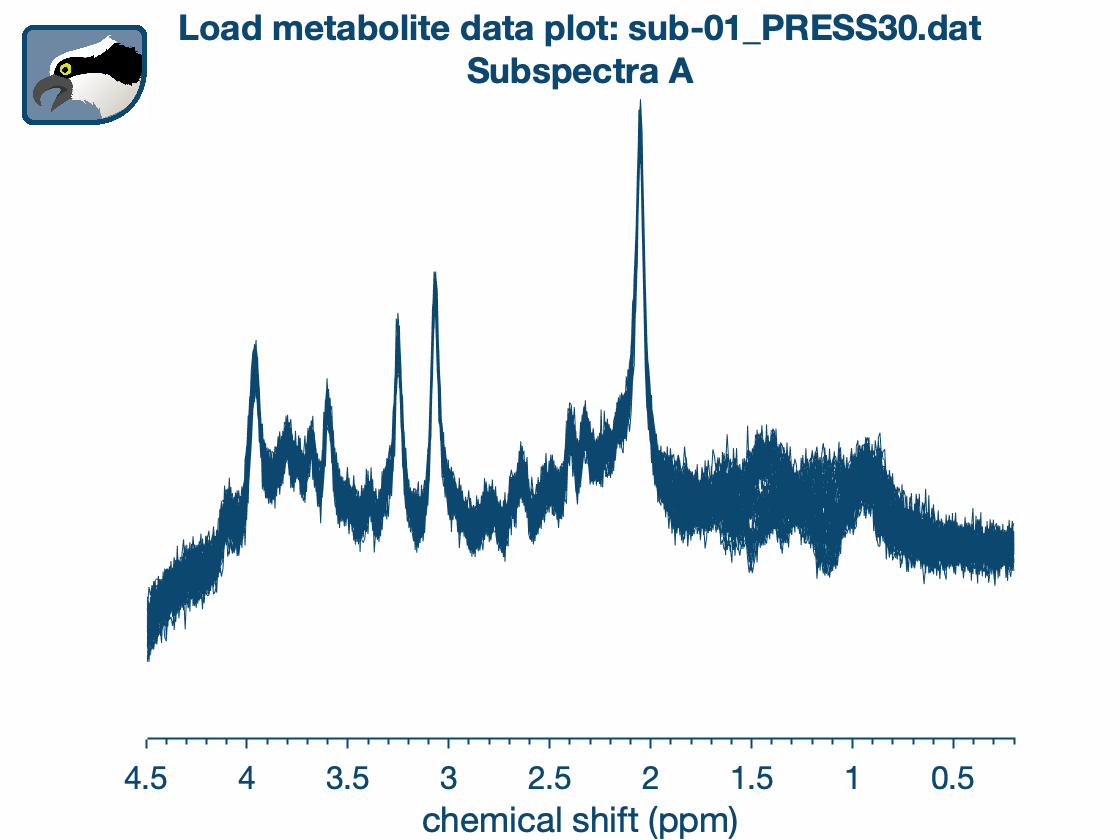

nToShow =1;
whatToShow = 'mets';
osp_plotLoad(demo, nToShow, whatToShow);

Each plot is scaled to its own maximum to be able to display the full dynamic range of each signal. We can clearly see the individual transients that these datasets consist of - during the next Osprey module, these will be aligned and averaged.

## Process data

The next Osprey command, `OspreyProcess`, branches out depending on the type of data that you have provided, and performs a bunch of processing steps, including the alignment of individual transients, weighted averaging, eddy-current-correction (if a water reference signal is available), water removal, pre-phasing and frequency referencing. Let's run it - we'll get back to the individual steps later.

[demo] = OspreyProcess(demo);

Timestamp September 23, 2021 13:26:33 Osprey 1.1.0  OspreyProcess
Processing data from dataset   2 out of   2 total datasets...

... done.
 Elapsed time 10.574532 seconds


### Visualizing processed data

We can, again, use an Osprey plot function to look at the different processed spectra. This overview shows you the individual averages before and after alignment of individual transients, the frequency drift before and after alignment, and the final averaged spectrum in the bottom right corner (again, these are scaled to their individual maxima, but for display purposes only).

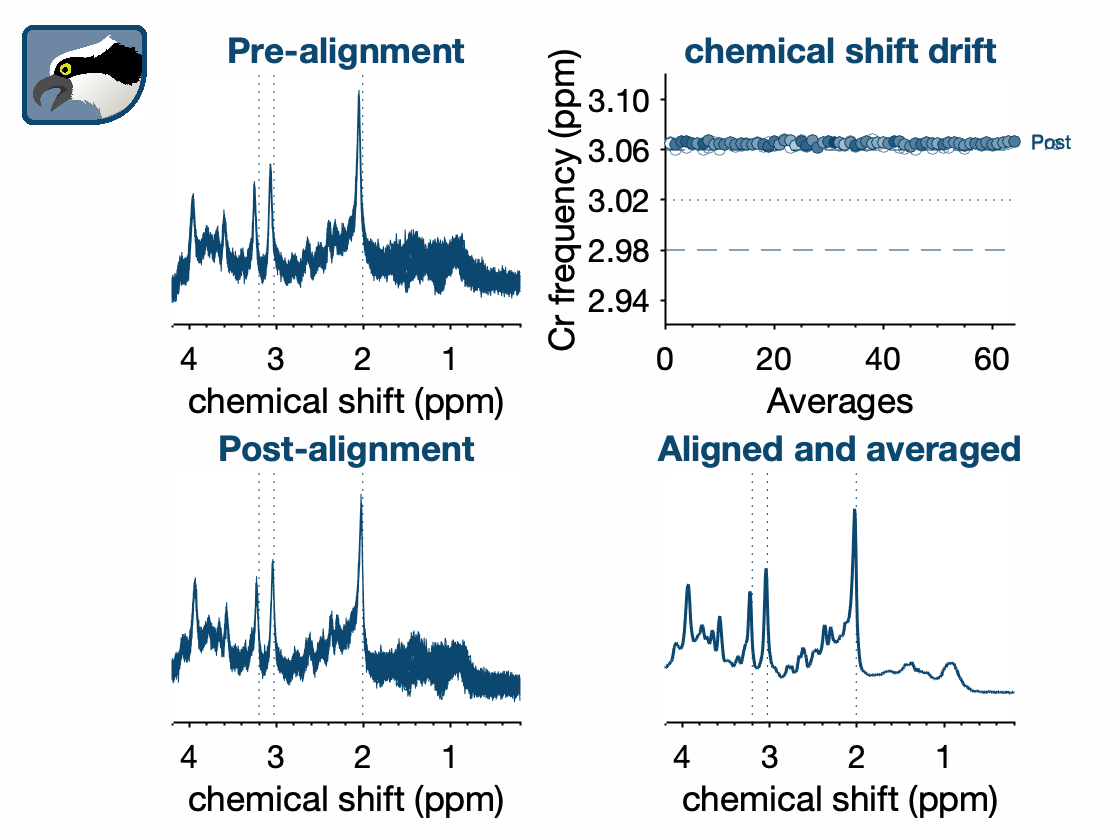

nToShowProc =1;
whatToShowProc = 'A';
osp_plotProcess(demo, nToShowProc, whatToShowProc);

These are the final spectra that Osprey will pass on to the modeling module in the next step.

## Fit data

The next Osprey command, `OspreyFit`, takes care of the core modeling of the data we have just processed. 

[demo] = OspreyFit(demo);

Timestamp September 23, 2021 13:26:46 Osprey 1.1.0  OspreyFit

Fitting metabolite spectra from dataset   1 out of   2 total datasets...

Running initial referencing...
Running preliminary analysis with reduced basis set...
Running final preliminary analysis step with full basis set...

Fitting metabolite spectra from dataset   2 out of   2 total datasets...

Running initial referencing...
Running preliminary analysis with reduced basis set...
Running final preliminary analysis step with full basis set...

... done.
 Elapsed time 78.343154 seconds

Fitting water reference spectra from dataset   1 out of   2 total datasets...

                                                 Norm   Rel norm   First-order   Rel first-order      Largest                              Comment
  I#    F#      f(x)      Df(x)   relDf(x)    of step    of step    optimality        optimality   eigenvalue   lambda      rho    ratio          
  23   183   1.5e+03        NaN        NaN    1.7e-11    1.2e-08         

### Visualizing fit data

You guessed it - there is another Osprey function to visualize fit results, `osp_plotFit`. This time, we have to pass the argument `'off'` to tell Osprey that these are un-edited data (Yes, we know - we are working to streamline this process!). This overview shows you the individual averages before and after alignment of individual transients, the frequency drift before and after alignment, and the final averaged spectrum in the bottom right corner (again, these are scaled to their individual maxima, but for display purposes only).

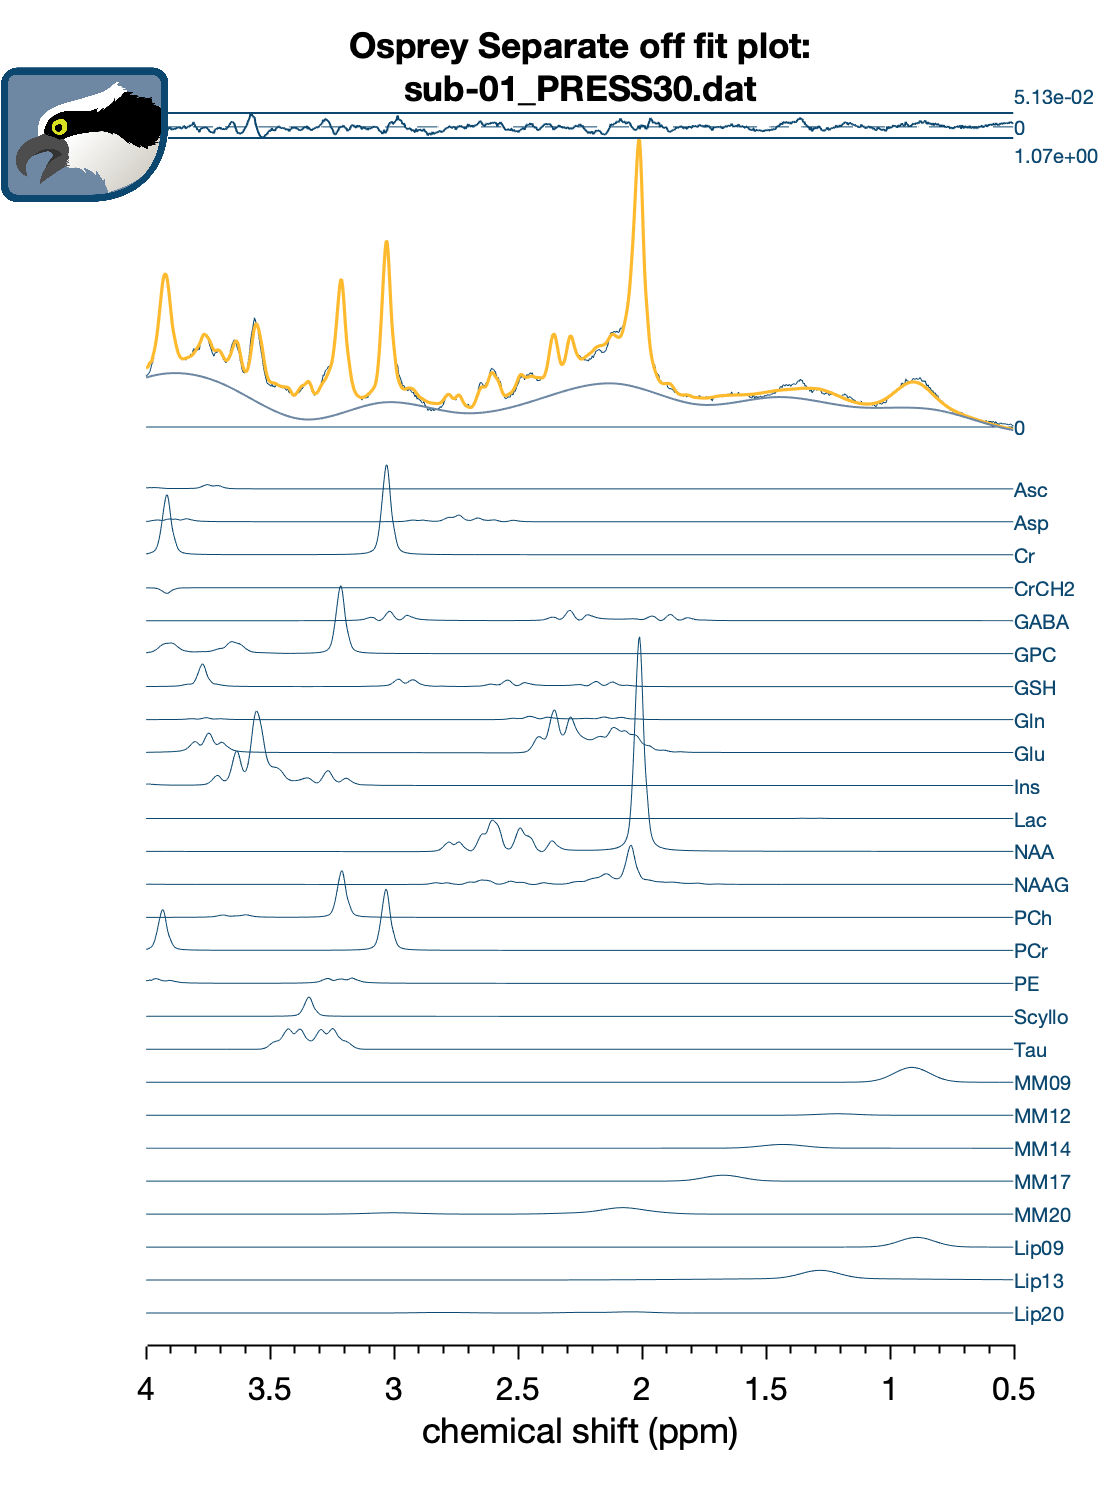

nToShowFit =1;
whatToShowFit = 'off';
osp_plotFit(demo, nToShowFit, whatToShowFit);

### Coregistering to structural anatomical images and segmentation

If you have downloaded SPM12 and added it to your MATLAB path, we can directly use the functions of this well-known neuroimaging toolbox to perform co-registration of our MRS voxels to theanatomical images provided in the job file. This is as simple as running the next Osprey command:

[demo] = OspreyCoreg(demo);

Timestamp September 23, 2021 13:28:08 Osprey 1.1.0  OspreyCoreg
Coregistering voxel from dataset   2 out of   2 total datasets...

... done.
 Elapsed time 5.997502 seconds


[demo] = OspreySeg(demo);

Timestamp September 23, 2021 13:28:15 Osprey 1.1.0  OspreySeg

Segmenting structural image from dataset   2 out of   2 total datasets...

... done.
 Elapsed time 11.898297 seconds


### Visualizing the binary voxel mask

Let's now visualize our voxel overlay, and check the results of the segmentation.

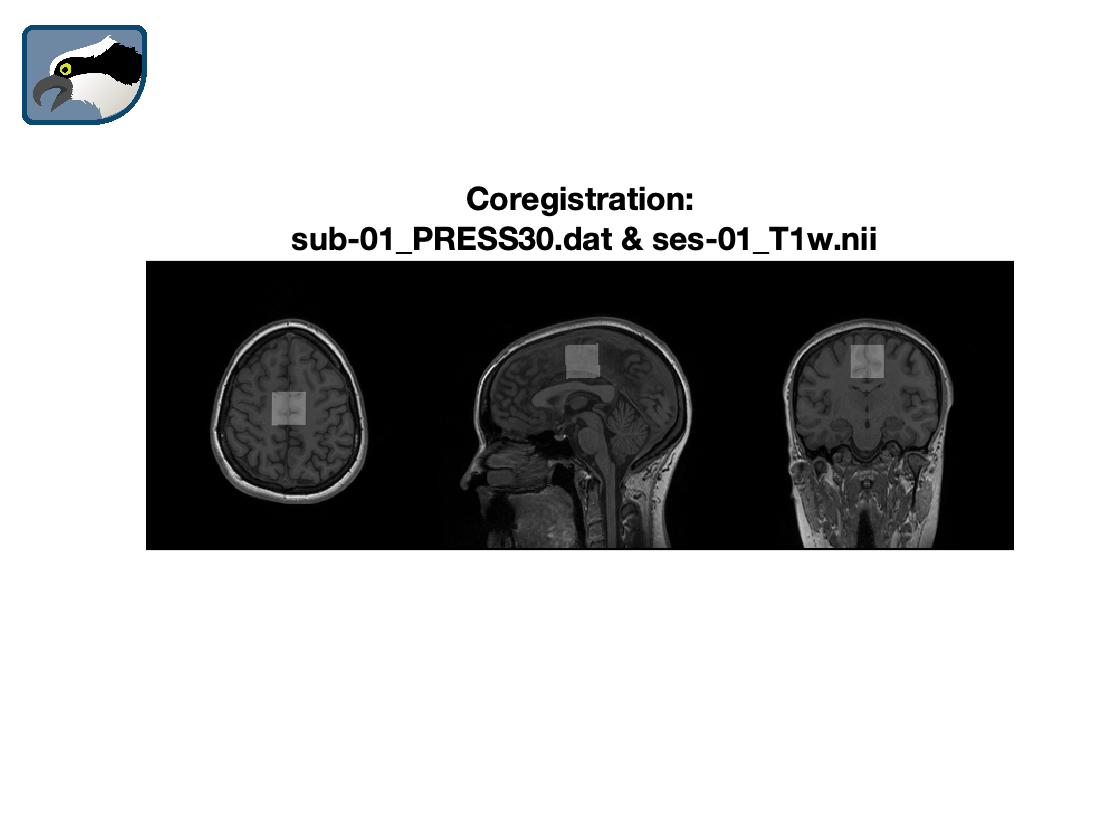

nToShowSeg =1;
osp_plotCoreg(demo, nToShowSeg);

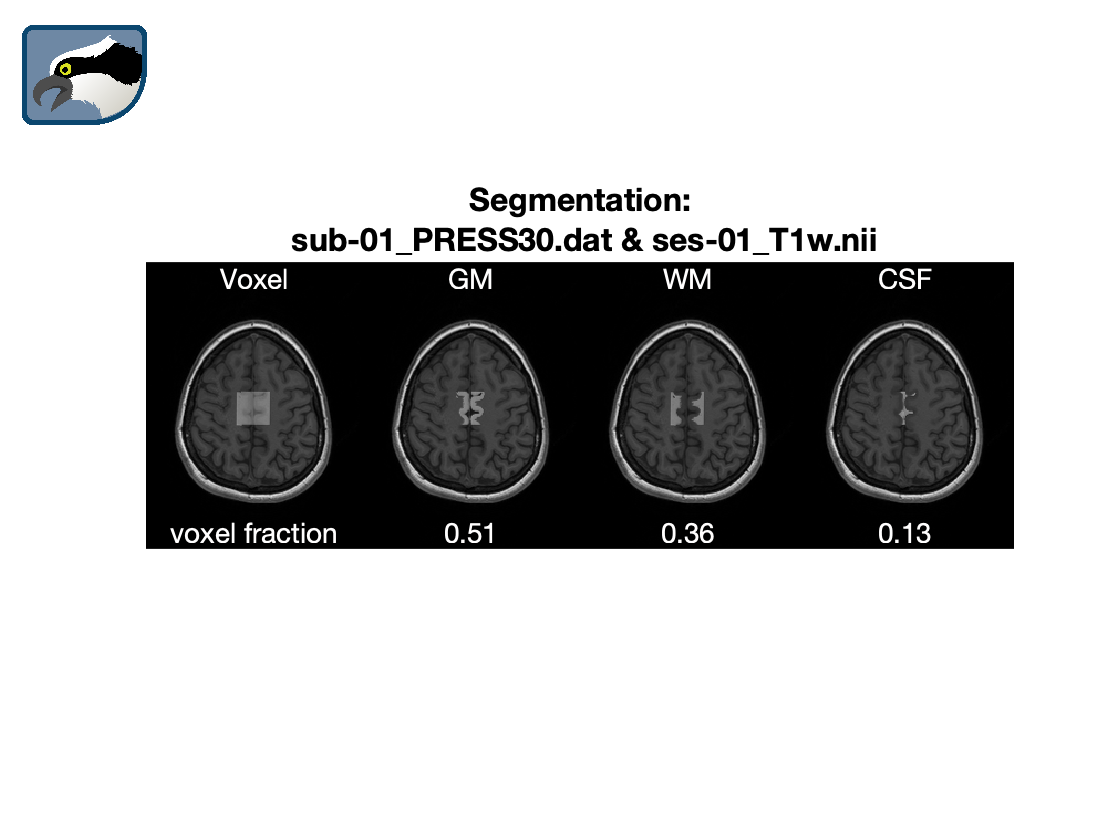

osp_plotSegment(demo, nToShowSeg);

### Quantification

This step pulls together the information from the modeling and the tissue segmentation step to deliver fully tissue- and relaxation-corrected metabolite level estimates.

[demo] = OspreyQuantify(demo);

Timestamp September 23, 2021 13:28:34 Osprey 1.1.0  OspreyQuantify

Quantifying dataset   2 out of   2 total datasets...
... done.
 Elapsed time 0.017059 seconds


### GUI

Call the GUI!

Timestamp September 23, 2021 13:28:36 Osprey 1.1.0  OspreyGUI


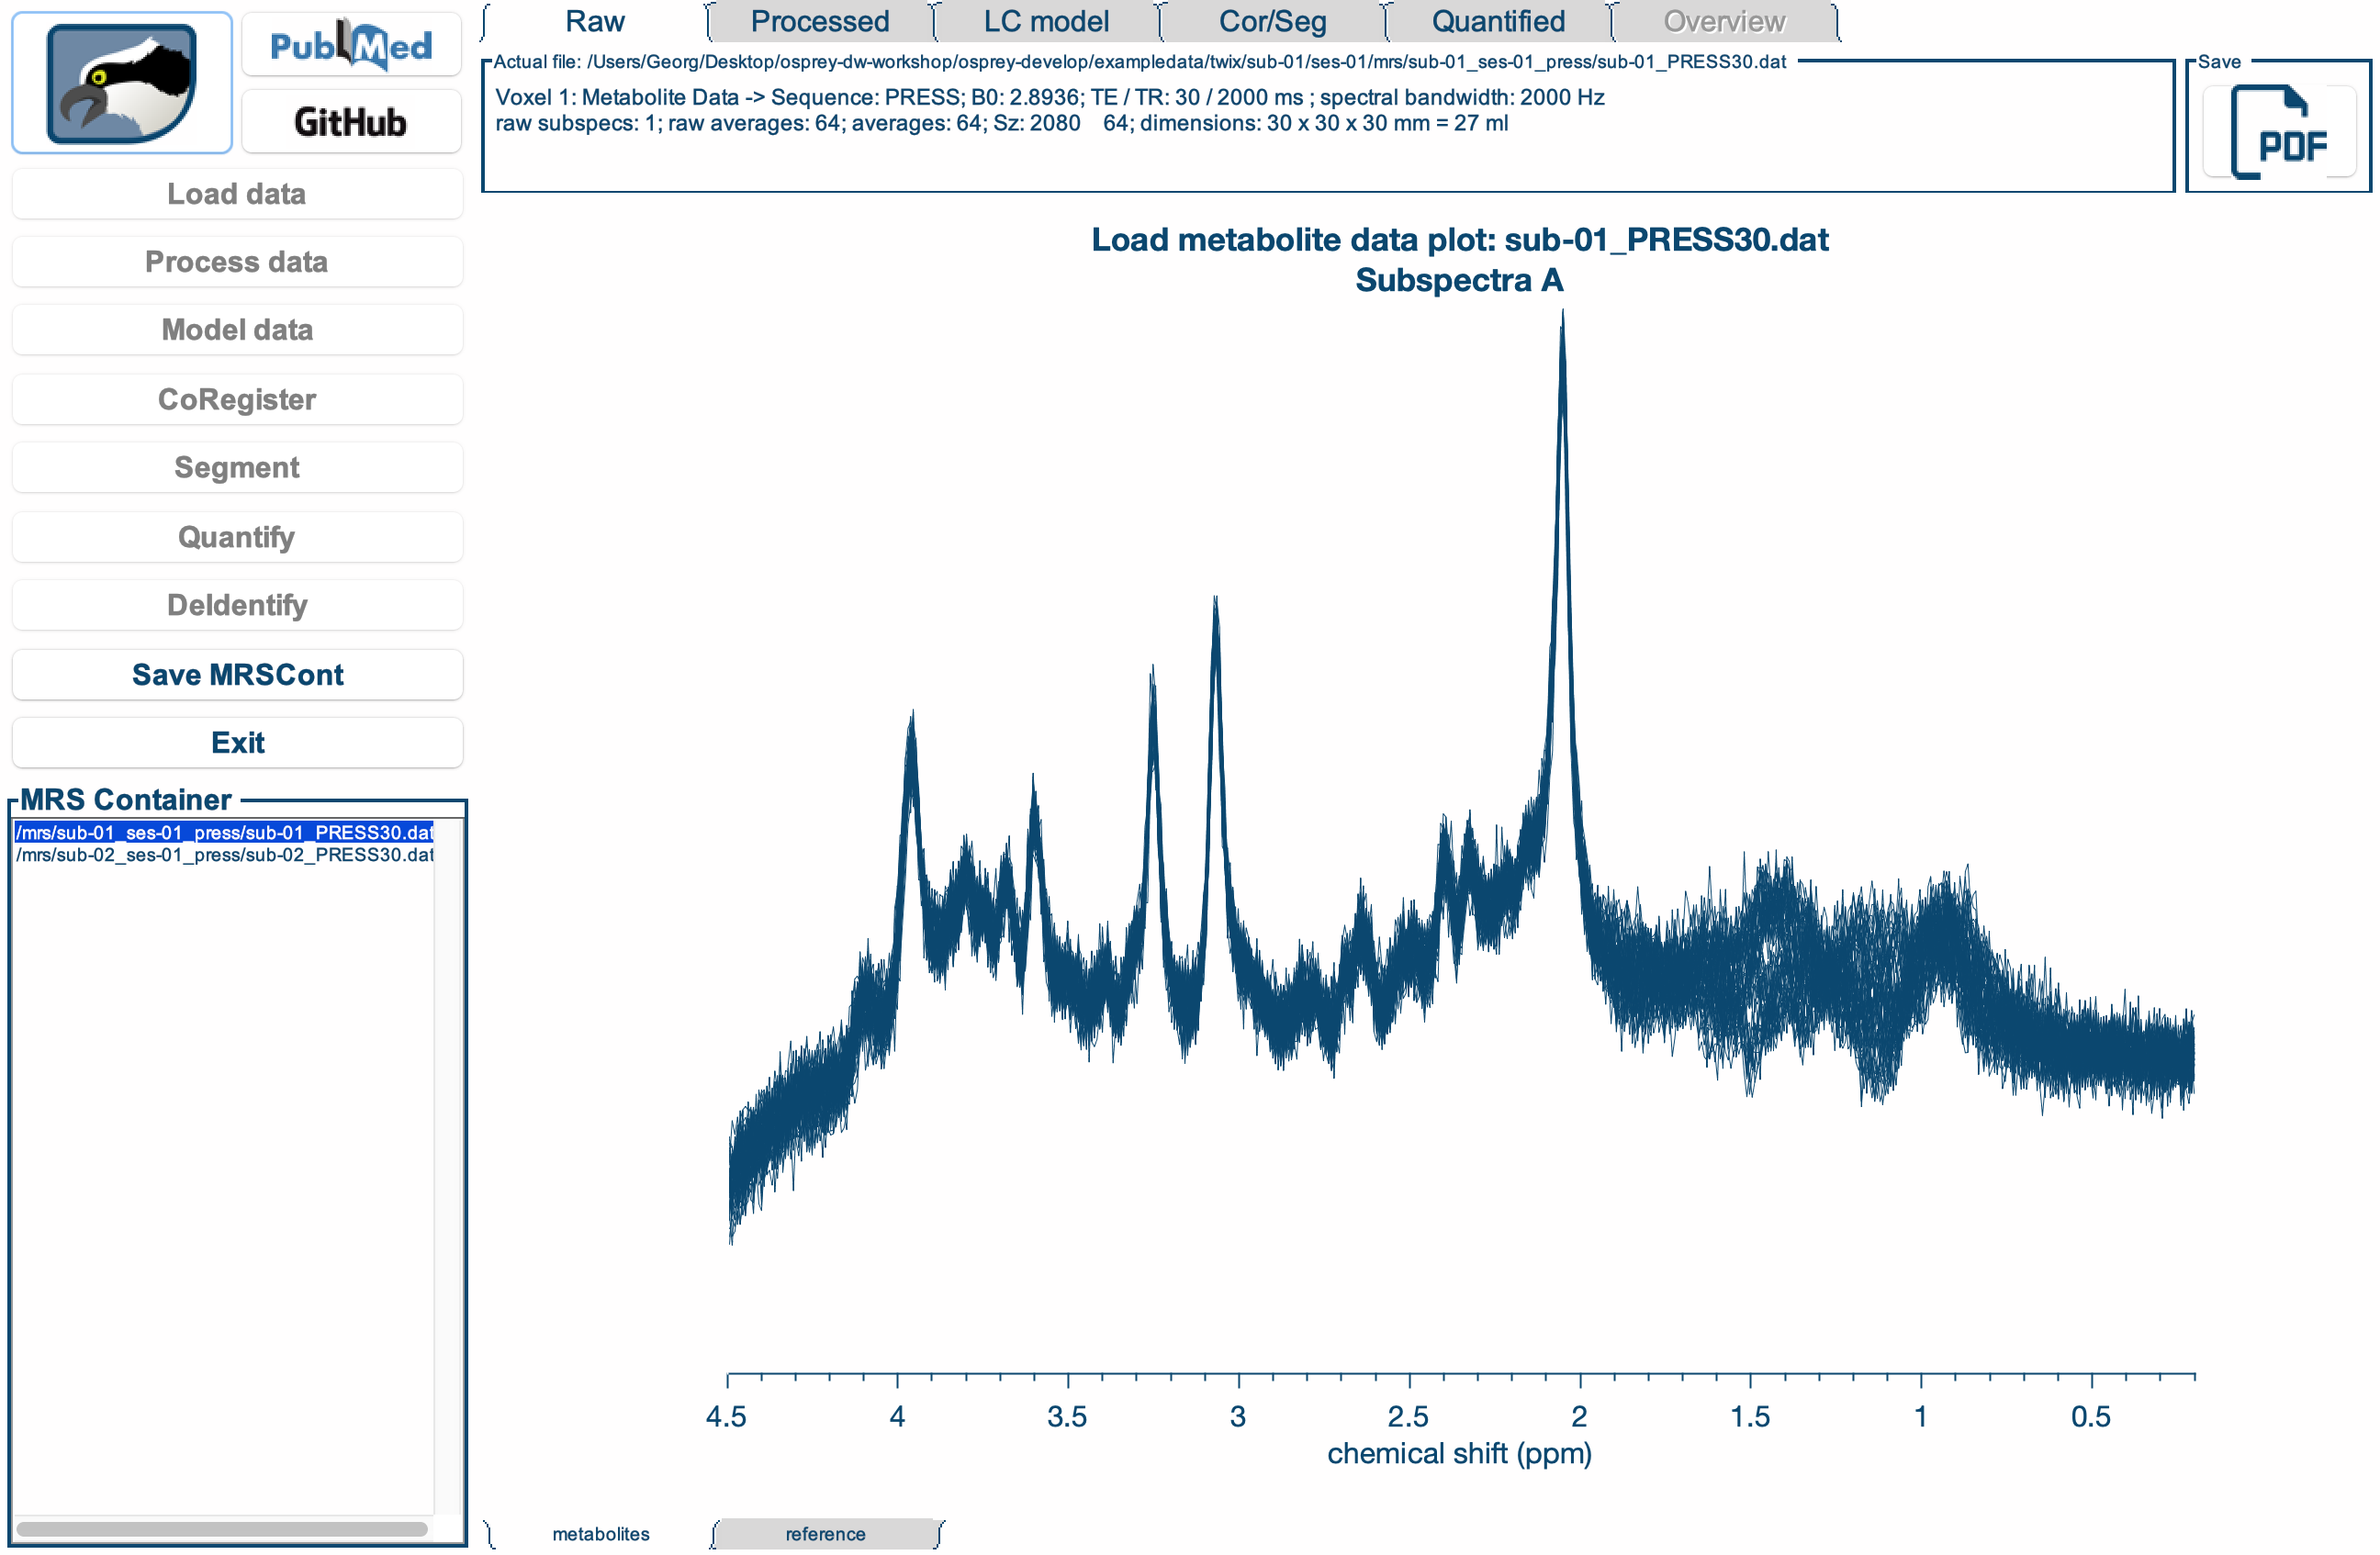

OspreyGUI(demo);